Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:08 |         5.50 |         15.1 |          0.0010 |
|      50 |          50 |       00:00:14 |         4.12 |          8.5 |          0.0010 |
|     100 |         100 |       00:00:18 |         3.04 |          4.6 |          0.0010 |
|     150 |         150 |       00:00:22 |         2.18 |          2.4 |          0.0010 |
|     200 |         200 |       00:00:26 |         1.52 |          1.2 |          0.0010 |
|     250 |         250 |       00:00:30 |         1.06 |          0.6 |          0.0010 |
|     300 |         300 |       00:00:34 |         0.76 |         

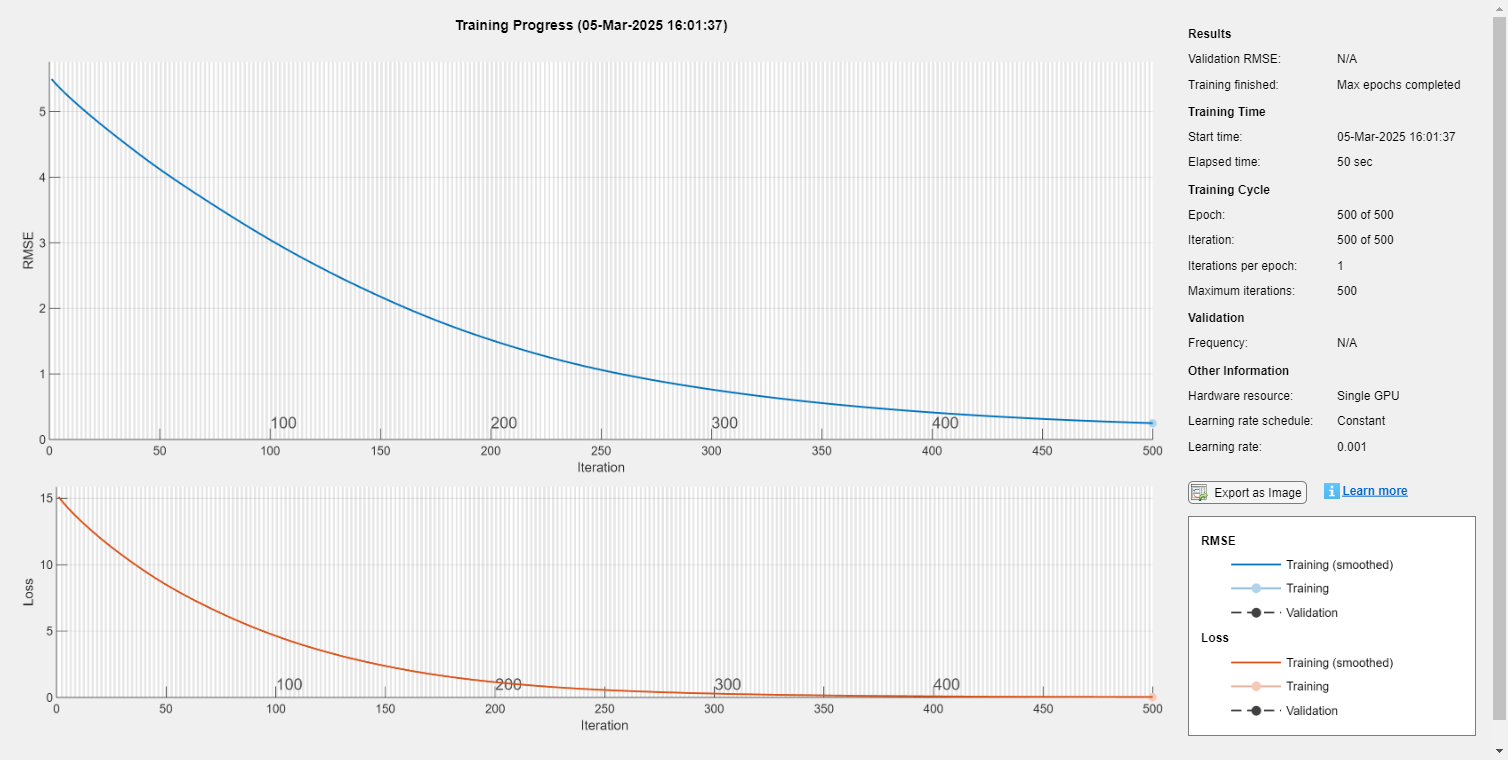

%%%% Load Pretrained Autoencoder Weights & Biases %%%%
we = autoenc5.EncoderWeights;  
be = autoenc5.EncoderBiases;  
%%%% Define BILSTM Network with Pretrained Weights %%%%
outPut_Size = size(we, 1);  % Should match encoded feature size (latent space)
inputSize = size(we, 2);    % Original waveform feature size

layer = fullyConnectedLayer(outPut_Size, ...
    'Weights', we, ...
    'Bias', be);

% Define LSTM-based Architecture
layers = [
    sequenceInputLayer(inputSize)
    layer
    lstmLayer(30, 'OutputMode', 'sequence')
    fullyConnectedLayer(inputSize)
    regressionLayer];

%%%% Training Options %%%%
options = trainingOptions('adam', ...
   'Plots', 'training-progress', ...
   'MiniBatchSize', 500, ...
   'MaxEpochs', 500, ...
   'SequencePaddingDirection','left',...
   'Shuffle', 'every-epoch', ...
   'GradientThreshold', 1, ...
   'Verbose', true, ...
   'ExecutionEnvironment', 'auto');

%%%% Reshape Data for LSTM %%%%
testwaveformDataSeq = permute(testwaveformData, [2, 1]); % Ensure correct format for LSTM

%%%% Train the Model %%%%
net = trainNetwork(testwaveformDataSeq', testwaveformDataSeq', layers, options);